# Questão 1

fquad = @(x)(x.^2)

fquad = function_handle with value:
    @(x)(x.^2)


var_s = 1/2 * integral(fquad,-1,1)

var_s = 0.3333

var_n = 1/4 * integral(fquad,-2,2)

var_n = 1.3333

var_y_H0 = var_n

var_y_H0 = 1.3333

var_y_H0 = var_n+var_s

var_y_H0 = 1.6667


$$\mathrm{VAR}\left\lbrack S+N\right\rbrack =\mathrm{VAR}\left\lbrack S\right\rbrack +\mathrm{VAR}\left\lbrack N\right\rbrack$$



$$H_0 :\mathrm{Null}\;\mathrm{Hypothesis}\to Y\;\mathrm{é}\;\mathrm{uma}\;\mathrm{V}\ldotp \mathrm{A}\;\mathrm{com}\;E\left\lbrack Y\right\rbrack =0\;\mathrm{e}\;\sigma_Y^2 =\theta =4/3$$



$$H_1 :\mathrm{Alternative}\;\textrm{Hypothesis}\to Y\;\mathrm{é}\;\textrm{uma}\;\mathrm{V}\ldotp \mathrm{A}\;\textrm{com}\;E\left\lbrack Y\right\rbrack =0\;\mathrm{e}\;\sigma_Y^2 =\theta =5/3$$



$$P\left\lbrack D_1 |H_0 \right\rbrack =\alpha =\int_{y|\Lambda \left(y\right)\ge \eta }^{\;} f_Y \left(y|H_0 \right)\mathrm{dy}$$



$$\beta =P\left\lbrack D_0 \left|H_1 \right.\right\rbrack$$



$$\Lambda \left(y\right)=\frac{f_Y \left(y|H_1 \right)}{f_Y \left(y|H_0 \right)}$$



$$f_Y \left(y\left|H_1 \right.\right)=f_N \left(n\right)*f_S \left(s\right)$$



$$f_Y \left(y\left|H_1 \right.\right)=\left\lbrace \begin{array}{cc}
0 & \mathrm{para}\;|y|>3\\
\frac{y+3}{8} & \mathrm{para}\;-3<y<1
\end{array}\right.$$



$$\frac{1}{4}$$

$$\mathrm{para}\;|y|>1$$



$$\frac{-y+3}{8}$$

$$\textrm{para}\;-3<y<1$$


a = -3;
b = 3;
L = 180;
t = linspace(a,b,L);

fs = zeros(1,L);
fn = fs;
Ls = L*2/(b-a)

Ls = 60

Ln = L*4/(b-a)

Ln = 120

fs(L/2-round(Ls/2):L/2+round(Ls/2))=1/2;
fn(L/2-round(Ln/2):L/2+round(Ln/2))=1/4;

fy = conv(fn,fs);
plot(t, fy(length(fy)/2-L/2:length(fy)/2+L/2-1));

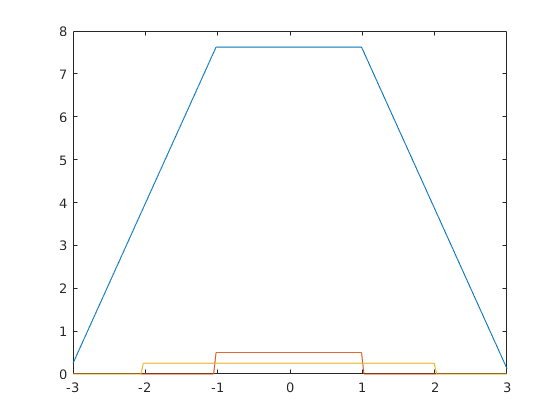

hold on
plot(t, fs);
plot(t, fn);
hold off

# Questão 2


$$f_Y \left(y\right)=\frac{1}{\sqrt{2\pi }}e^{-\frac{{\left(y-m_j \right)}^2 }{2}}$$



$$\mathrm{exp}\left(\frac{{\left(y-m_0 \right)}^2 }{2}-\frac{{\left(y-m_1 \right)}^2 }{2}\right)$$



$$f_Y \left(y\right)=\frac{1}{\sqrt{2\pi }}e^{-\frac{y^2 }{2}}$$



$$Q\left(\gamma \right)$$


# Questão 3


$$f_{\mathit{\mathbf{Y}}} \left(\mathit{\mathbf{y}}|H_0 \right)=\prod_{i=1}^K f_{Y_i } \left(y_i |H_0 \right)=\frac{1}{{\left(\sigma \sqrt{2\pi }\right)}^K }\mathrm{exp}\left(-\frac{1}{2\sigma^2 }\sum_{i=1}^K {y_i }^2 \right)$$



$$f_{\mathit{\mathbf{Y}}} \left(\mathit{\mathbf{y}}\left|H_1 \right.\right)=\prod_{i=1}^K f_{Y_i } \left(y_i \left|H_1 \right.\right)=\frac{1}{{\left(\sigma \sqrt{2\pi }\right)}^K }\exp \left(-\frac{1}{2\sigma^2 }\sum_{i=1}^K {\left(y_i -m\right)}^2 \right)$$



$$\exp \left(-\frac{1}{2\sigma^2 }\sum_{i=1}^K \left(y_i -m\right)-{y_i }^2 \right)$$



$$\exp \left(-\frac{1}{2\sigma^2 }\sum_{i=1}^K m^2 -2\mathit{my}\right)$$



$$\exp \left(-\frac{1}{2\sigma^2 }\left(Km^2 -2m\sum_{i=1}^K y\right)\right)$$



$$\exp \left(-\frac{1}{2\sigma^2 }\left(Km^2 -2\mathrm{mK}\bar{Y_K } \right)\right)$$



$$\bar{Y_K } =\frac{1}{K}\sum_{i=1}^K \textrm{y}$$



$$\frac{\sigma^2 \mathrm{ln}\eta }{\mathit{Km}}+\frac{m}{2}$$


syms sig m K Y mi
eq = -1/(2*sig) * (K*m^2-2*m*K*Y) == log(mi)

$$eq = -\frac{K\,m^{2}-2\,K\,Y\,m}{2\,\mathrm{sig}}=\log\left(\mathrm{mi}\right)$$

isolate(eq, Y)

$$ans = Y=\frac{K\,m^{2}+2\,\mathrm{sig}\,\log\left(\mathrm{mi}\right)}{2\,K\,m}$$

# Questão 4


$$f_Y \left(y|H_0 \right)=\frac{1}{\sqrt{2\pi }}\exp \left(-\frac{{\left(y_i +1\right)}^2 }{2}\right)$$



$$f_Y \left(y\left|H_1 \right.\right)=\frac{1}{\sqrt{2\pi }}\exp \left(-\frac{{\left(y_i -1\right)}^2 }{2}\right)$$



$$\exp \left(\frac{{\left(y_i +1\right)}^2 }{2}-\frac{{\left(y_i -1\right)}^2 }{2}\right)$$



$$\exp \left(2y\right)$$


L = 100;
a = -1;
b = 1;
load('Transmitido.mat');
load('Recebido.mat');
eta = linspace(a,b,L);
D = zeros(1,length(X));
BER = zeros(1,L);

for i = 1:L % limiar
    aux = 0;
    for j = 1:length(X) % dado
        if Y(j) > eta(i) % Decisão
            D(j)=1;
        else
            D(j)=-1;
        end
        if D(j)~=X(j) % contagem de erro
            aux = aux+1;
        end
    end
    BER(i) = aux/length(X);
end

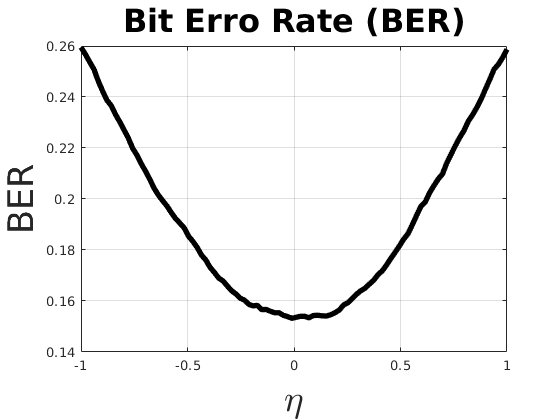

plot(eta,BER,'Color','black','LineWidth',4);
grid on
title('Bit Erro Rate (BER)','FontSize',24)
xlabel('\eta','FontSize',28)
ylabel('BER','FontSize',26)